Load and analyze noisy rows between frames

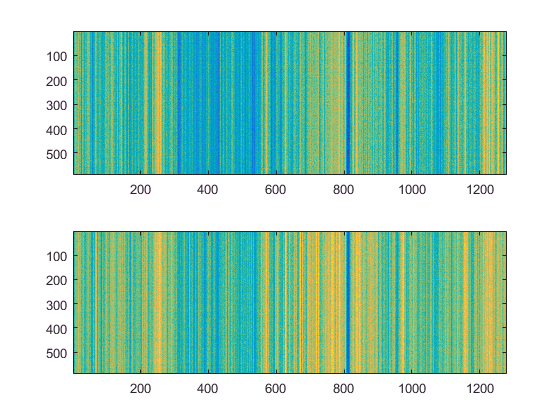

%% load images
% Images = photronReadImages(exper{1}, 2,1000,1,3000,1);
% [maxTrajectories, meanTrajectories, RowOverTime, RowOverTimeCut, RowNumbers] = Movie_follow_maxima_in_row(Images,12,[],0.05,[],1);

%% analyze noisy difference between odd and evens
Rows2AvgOn = RowOverTime(1:1180,:);
Rows2AvgOnOdd = Rows2AvgOn(1:2:end,:);
Rows2AvgOnEven = Rows2AvgOn(2:2:end,:);

figure;
subplot(2,1,1); imagesc(Rows2AvgOnEven);
 subplot(2,1,2); imagesc(Rows2AvgOnOdd);

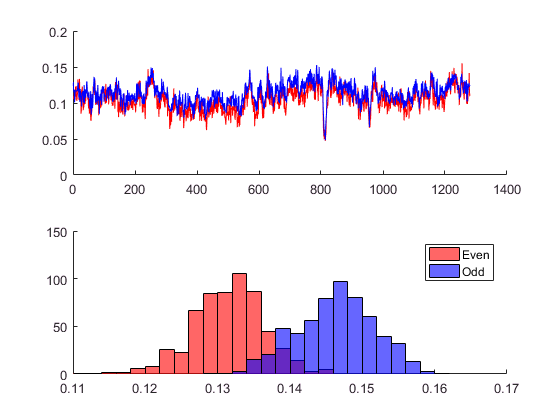

meanRowOdd = mean(Rows2AvgOnOdd,1);
meanRowEven = mean(Rows2AvgOnEven,1);

figure; 
subplot(2,1,1); hold on;
plot(meanRowEven,'r');plot(meanRowOdd,'b');
subplot(2,1,2); hold on;
histogram(Rows2AvgOnEven(:,570),'FaceColor','r');histogram(Rows2AvgOnOdd(:,570),'FaceColor','b');
legend({'Even','Odd'});

It can be seen that in this case the even rows are less noisy. For the first shot I'll try to use them only.

Cross corelation of signals:

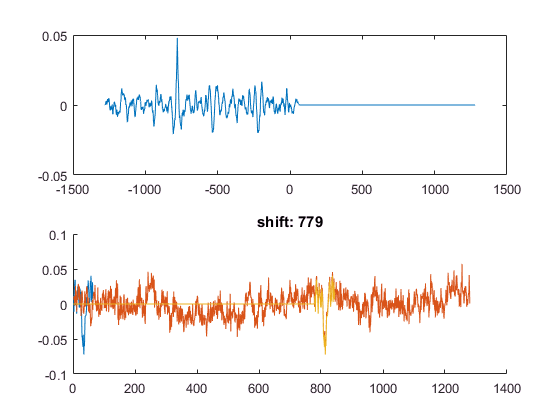

%--- use the even averaged signal as the "true" signal of asperities:
RowOverTime2Use = RowOverTimeEven;
ReferenceSignal = RowOverTime2Use(1,:);
%--- use the deep scratch as reference:
scratchCoordinates = 780:845;
DeepScratch = ReferenceSignal(scratchCoordinates);
%--- cross correlate the signals just for sanity:
% sig1 = RowOverTime2Use(1,:);
% sig2 = RowOverTime2Use(800,:);
sig1 = DeepScratch;
sig2 = ReferenceSignal;
sig1 = sig1-mean(sig1);
sig2 = sig2-mean(sig2);
[XcrScratch, lag]= my_xcorr(sig1, sig2);

figure;
subplot(2,1,1);
plot(lag,XcrScratch);
subplot(2,1,2); hold on;
plot(sig1); plot(sig2);
% XcrScratch(lag==0)=0;
[m,i] = max(XcrScratch);
shift = -lag(i);
plot([zeros(1,shift), sig1]);
title(['shift: ',num2str(shift)]);

%--- cross correlate between pairs before-after event
eventFrame = 599;    % actually, the row in RowOverTime2Use. accurate fot the scratch only.
rowsBefore = 1:eventFrame-1;
rowsAfter= eventFrame+1:size(RowOverTime2Use,1);
% rowsBefore = 550:eventFrame-1;
% rowsAfter= eventFrame+1:650;
pairsMatrix = allPairs(rowsBefore,rowsAfter);
shiftVec = zeros(size(pairsMatrix,1),1);
corrVec = zeros(size(pairsMatrix,1),1);
XcrScratchMatrix = [];
lagMatrix = [];
for i = 1:size(pairsMatrix,1)
    sigBefore = RowOverTime2Use(pairsMatrix(i,1),800:840);
    sigAfter = RowOverTime2Use(pairsMatrix(i,2),800:840);
    sigBefore = sigBefore-mean(sigBefore);
    sigAfter = sigAfter-mean(sigAfter);
    [XcrScratch, lag]= my_xcorr(sigBefore, sigAfter);
    [m,I] = max(XcrScratch);
    shiftVec(i) = -lag(I);
    corrVec(i) = m;
    XcrScratchMatrix = cat(1,XcrScratchMatrix,XcrScratch);
    lagMatrix = cat(1,lagMatrix,lag);
end